clear all;
%rav = ravdess_database();
emdb = berlin_emotional_database();
%hum = humaine();

%rav_emotions = rav.Labels;
emdb_emotions = emdb.Labels;
num_emotions = number_emotions(emdb_emotions);

%rav.Labels = 1:length(rav.Files);
emdb.Labels = 1:length(emdb.Files);
%hum.Labels = 1:length(hum.Files);

%rav_info = audioinfo(rav.Files{1,1});
fs = 8000;

new_emdb = transform (emdb, @(x,info) resample_datastore(x, info, ...
                                fs), 'IncludeInfo', true);
%new_hum = transform (emdb, @(x,info) resample_datastore(x, info, ...
%                                fs), 'IncludeInfo', true);


%ads = combine(rav, new_emdb, new_hum);
%shAds = shuffle(ads);
%subAds1 = partition(shAds,3,1);
%subAds2 = partition(shAds,3,2);
%subAds3 = partition(shAds,3,3);

features = extract_features(new_emdb, fs);
fz = 1;
for e = 1:length(features) 
    s = size(features{1,e});
    f(fz:fz+s(1)-1,1:s(2)) = features{1,e};
    f(fz:fz+s(1)-1, s(2)+1) = num_emotions(e);
    fz = fz + s(1);
end
% x = f(:,1);
% y = f(:,2);
% z = f(:,3);
% colors = color(f(:,4));
% for c = 1:length(colors)
%     plot3(x(c),y(c),z(c),'.','Color',colors(c));
%     hold on;
% end
% grid on;

% colors = color(f(:,end));
all_types= unique(f(:,end));
g = tsne(f(:, 1:end-1));

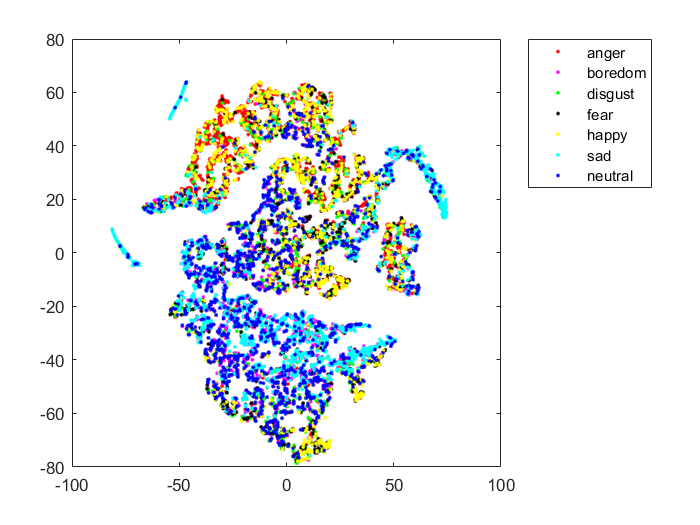

l = length(g);
figure;
for i = 1:length(all_types)
    idx = find(f(1:l,end) == all_types(i));
    c = color(all_types(i));
    plot(g(idx,1), g(idx,2), ['.' c{1}]);
    hold on;
end
labels = {'anger', 'boredom', 'disgust', 'fear', 'happy', 'sad','neutral'};
legend( labels,'Location','northeastoutside');